# Computational Methods in Physics (PHY4605) - **Loops**

## Overview

Loops are a programming concept that repeat a block of code until a condition is met. Loops are useful for performing repetitive tasks without writing the same code multiple times. The `for` statement is used to repeat a block of statements a fixed number of times where the number of repetitions must be determined in advance, is sometimes called *determinate repetition*. However, it often happens that the condition to end a loop is only satisfied during the execution of the loop itself. Such a structure is called *indeterminate repetition*—this type of loop is called `while` loop.

## The `for` Loop

In general the most common form of the for loop is: 

Note the following points carefully:

- `j : k` is a vector with elements $j,j+1,j+2\;,\ldotp \ldotp \ldotp ,\;k$. The vector can be replaced with `j : m : k` where the elements $j,j+m,j+2m,\ldotp \ldotp \ldotp ,\;k$ such that the last element does not exceed $k$ if $m>0$ or is not less than $k$ if $m<0$.

- *index* must be a variable. Each time through the loop it will contain the next element of the vector and statements (there may be one or more) are carried out for each of these values.

### Physics Pinpoint 🔎: Cooling of a Drink

Many problems in science and engineering involve modeling a process where the main variable is repeatedly updated over a period of time. Here is an example of such an update process.

A can of orange juice at temperature 25°C is placed in a fridge, where the ambient temperature $F$ is 10°C. We want to find out how the temperature of the orange juice changes over a period of time. A standard way of approaching this type of problem is to break the time period up into a number of small steps, each of length $\textrm{dt}$. If $T_i$ is the temperature at the beginning of step $i$, we can use the following model to get $T_{i+1}$ from $T_i$:


$$T_{i+1} =T_i -K\;\mathrm{dt}\;\left(T_i -F\right)$$


where $K$ is a constant parameter depending on the insulating properties of the can, and the thermal properties of orange juice. Assume that units are chosen so that time is in minutes. The following script implements this scheme. To make the solution more general, take the starting time as $a$, and the end time as $b$. This is the time (in minutes) between successive rows of output.

K = 0.05;
F = 10;
a = 0;
b = 60;
Time = a;
T = 25; 
TimeIncrement = 3;
OutputInt = 1; % The time interval for displaying outputs
disp('Time        Temperature');

Time        Temperature


fprintf('%4.0f%16.2f\n', Time, T);

   0           25.00


plot(Time, T, 'k*');
hold on
xlabel('Time, t (minute)');
ylabel('Temperature, T (°C)')
for Time = a + TimeIncrement : TimeIncrement : b
    T = T - K * TimeIncrement * (T - F);
    if abs(rem(Time, OutputInt)) < 1e-6
        fprintf('%4.0f%16.2f\n', Time, T);
        plot(Time, T, 'k*');
    end
end

   3           22.75
   6           20.84
   9           19.21
  12           17.83
  15           16.66
  18           15.66
  21           14.81
  24           14.09
  27           13.47
  30           12.95
  33           12.51
  36           12.13
  39           11.81
  42           11.54
  45           11.31
  48           11.11
  51           10.95
  54           10.80
  57           10.68
  60           10.58


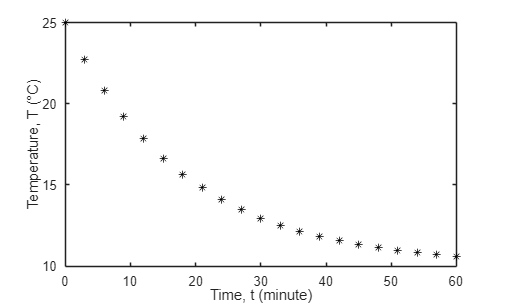

hold off

## The `while` Loop

Determinate loops all have in common the fact that you can work out in principle exactly how many repetitions are required before the loop starts. But in the next example, there is no way in principle of working out the number of repeats, so a different structure is needed.

In general the while statement looks like this: 

The `while` construct repeats statements while its condition remains true. The condition therefore is the condition to repeat once again. The condition is tested each time before statements are repeated. Since the condition is evaluated before statements are executed, it is possible to arrange for statements not to be executed at all under certain circumstances. Clearly, condition must depend on statements in some way, otherwise the loop will never end. Recall that a vector condition is considered true only if all its elements are nonzero.

### Physics Pinpoint 🔎: Projectile Trajectory

We would like to know now when and where a projectile will hit the ground. Although this problem can be solved with a determinate loop, it is of interest also to see how to solve it with an indeterminate `while` loop. The idea is to calculate the trajectory repeatedly with increasing time, while the vertical displacement, $y$ remains positive. Here’s the script:

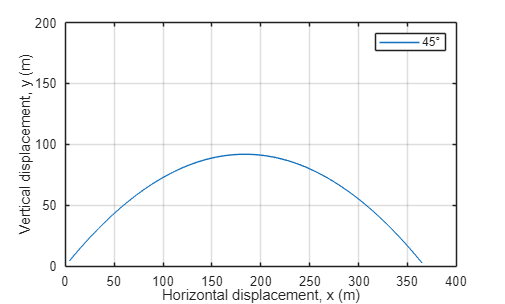

TimeIncrement = 0.1;
GravityAcceleration = 9.8;
InitialVelocity = 60;
AngleDeg = 45;
AngleRad = AngleDeg * pi / 180; 
XPosition = NaN(1, 1000); 
YPosition = NaN(1, 1000);
Y = 0; 
Time = 0;
i = 1;
while Y >= 0
    Time = Time + TimeIncrement;
    i = i + 1;
    Y = InitialVelocity * sin(AngleRad) * Time - GravityAcceleration * Time^2 / 2;
    if Y >= 0
        XPosition(i) = InitialVelocity * cos(AngleRad) * Time;
        YPosition(i) = Y;
    end
end
plot(XPosition, YPosition, DisplayName = string(AngleDeg) + "°");
xlim([0, 400]); ylim([0, 200]);
xlabel('Horizontal displacement, x (m)');
ylabel('Vertical displacement, y (m)');
grid on
legend

## The `break` and `continue` Statements

The `break` statement terminates the execution of a `for` or `while` loop. Statements in the loop after the `break` statement do not execute. In nested loops, `break` exits only from the loop in which it occurs. Control passes to the statement that follows the `end` of that loop. 

The following script performs summation of a sequence of random numbers. When the sum is greater than an upper limit, the loop exits using a `break` statement:

Limit = 5;
Total = 0;
Index = 1;
while true
    RandomNumber = rand;
    fprintf('Random number #%d: %.4f\n', Index, RandomNumber);
    Total = Total + RandomNumber;
    if Total > Limit
        fprintf('Total: %.4f\n', Total);
        break;
    end
    Index = Index + 1;
end

Random number #1: 0.9134
Random number #2: 0.6324
Random number #3: 0.0975
Random number #4: 0.2785
Random number #5: 0.5469
Random number #6: 0.9575
Random number #7: 0.9649
Random number #8: 0.1576
Random number #9: 0.9706


Total: 5.5193


The `continue` statement passes control to the next iteration of a `for` or `while` loop. It skips any remaining statements in the body of the loop for the current iteration. The program continues execution from the next iteration. `continue` applies only to the body of the loop where it is called. In nested loops, `continue` skips remaining statements only in the body of the loop in which it occurs.

The script below displays the multiples of 7 from 1 through 50. If a number is not divisible by 7, use `continue` to skip the `fprintf` statement and pass control to the next iteration of the for loop.

for Number = 1 : 50
    if rem(Number, 7)
        continue;
    end
    fprintf('Divisible by 7: %d\n', Number);
end

Divisible by 7: 7
Divisible by 7: 14
Divisible by 7: 21
Divisible by 7: 28
Divisible by 7: 35
Divisible by 7: 42
Divisible by 7: 49


### Physics Pinpoint 🔎: Capacitor Charges

When a resistor ($R$), capacitor ($C$) and battery ($V$) are connected in series, a charge $Q$ builds up on the capacitor according to the formula $Q\left(t\right)=CV\left(1-e^{-t/RC} \right)$ if there is no charge on the capacitor at time $t=0\;\mathrm{s}$. The problem is to monitor the charge on the capacitor every 0.1 seconds in order to detect when it reaches a level of 8 units of charge, given that $V=9\;\mathrm{V}$, $R=4\;\Omega$ and $C=1\;\mathrm{F}$. Write a program which displays the time and charge every 0.1 seconds until the charge first exceeds $8\;\mathrm{C}$ (i.e. the last charge displayed must exceed 8). Once you have done this, rewrite the program to display the charge until the charge first exceeds $10\;\mathrm{C}$.

Limit = 8

Limit = 8

V = 9;
R = 4;
C = 1;
for Time = 0 : 0.1 : 1e8
    Q = C * V * (1 - exp(-Time/(R * C)));
    fprintf('%2.2f%12.4f\n', Time, Q);
    plot(Time, Q, 'k.');
    hold on
    if Q > Limit
        break;
    end
end

0.00      0.0000
0.10      0.2222
0.20      0.4389
0.30      0.6503
0.40      0.8565
0.50      1.0575
0.60      1.2536
0.70      1.4449
0.80      1.6314
0.90      1.8134
1.00      1.9908
1.10      2.1639
1.20      2.3326
1.30      2.4973
1.40      2.6578
1.50      2.8144
1.60      2.9671
1.70      3.1161
1.80      3.2613
1.90      3.4030
2.00      3.5412
2.10      3.6760
2.20      3.8075
2.30      3.9357
2.40      4.0607
2.50      4.1826
2.60      4.3016
2.70      4.4176
2.80      4.5307
2.90      4.6411
3.00      4.7487
3.10      4.8537
3.20      4.9560
3.30      5.0559
3.40      5.1533
3.50      5.2482
3.60      5.3409
3.70      5.4312
3.80      5.5193
3.90      5.6053
4.00      5.6891
4.10      5.7708
4.20      5.8506
4.30      5.9283
4.40      6.0042
4.50      6.0781
4.60      6.1503
4.70      6.2206
4.80      6.2893
4.90      6.3562
5.00      6.4215
5.10      6.4851
5.20      6.5472
5.30      6.6078
5.40      6.6668
5.50      6.7244
5.60      6.7806
5.70      6.8354
5.80      6.88

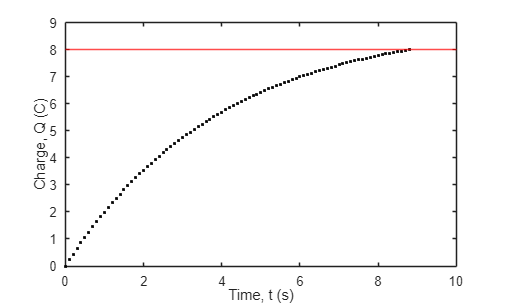

hold off
xlabel('Time, t (s)');
ylabel('Charge, Q (C)');
yline(Limit, 'r');